# Growth Kinetics Analaysis

clear;
clc;

## Wild Type

### n=1

WT_1 = "/Users/Priya/testoutput/TestMammaryOrganoid/MammaryCellCycleModel/WT/n=1/results_from_time_0/location.dat";
[WT_1_numberofcells, x, WT_1_yLE, WT_1_yME, WT_1_yTotal, WT_1_ME, WT_1_LE] = TimeVsNoCells(WT_1);

### n=2

WT_2 = "/Users/Priya/testoutput/TestMammaryOrganoid/MammaryCellCycleModel/WT/n=2/results_from_time_0/location.dat";
[WT_2_numberofcells, x, WT_2_yLE, WT_2_yME, WT_2_yTotal, WT_2_ME, WT_2_LE] = TimeVsNoCells(WT_2);

### n=3

WT_3 = "/Users/Priya/testoutput/TestMammaryOrganoid/MammaryCellCycleModel/WT/n=3/results_from_time_0/location.dat";
[WT_3_numberofcells, x, WT_3_yLE, WT_3_yME, WT_3_yTotal, WT_3_ME, WT_3_LE] = TimeVsNoCells(WT_3);

### n=4

WT_4 = "/Users/Priya/testoutput/TestMammaryOrganoid/MammaryCellCycleModel/WT/n=4/results_from_time_0/location.dat";
[WT_4_numberofcells, x, WT_4_yLE, WT_4_yME, WT_4_yTotal, WT_4_ME, WT_4_LE] = TimeVsNoCells(WT_4);

### n=5

WT_5 = "/Users/Priya/testoutput/TestMammaryOrganoid/MammaryCellCycleModel/WT/n=5/results_from_time_0/location.dat";
[WT_5_numberofcells, x, WT_5_yLE, WT_5_yME, WT_5_yTotal, WT_5_ME, WT_5_LE] = TimeVsNoCells(WT_5);

% combine data tables from all experiments into one table

yTotal_WT = cat(2,WT_1_yTotal,WT_2_yTotal,WT_3_yTotal,WT_4_yTotal,WT_5_yTotal);
yLE_WT = cat(2,WT_1_yLE,WT_2_yLE,WT_3_yLE,WT_4_yLE,WT_5_yLE);
yME_WT = cat(2,WT_1_yME,WT_2_yME,WT_3_yME,WT_4_yME,WT_5_yME);

% transpose data table
time = x.';
yTotal_WT_ = yTotal_WT.';
yLE_WT_ = yLE_WT.';
yME_WT_ = yME_WT.';

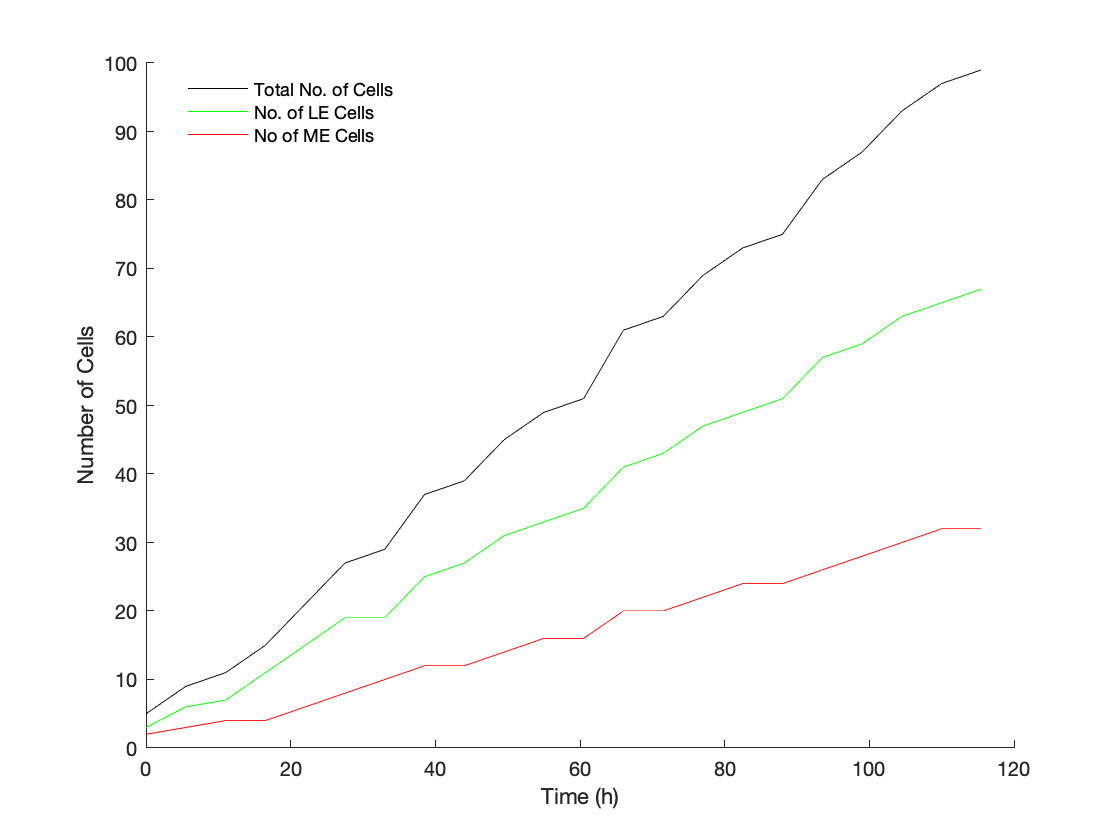

% plot data with error bars
clf

hold on; 

WTtotal = shadedErrorBar(time(:,1:55:end),yTotal_WT_(:,1:55:end),{@mean,@std},'lineProps','k','transparent',0);

hold off;

hold on;

WTLE = shadedErrorBar(time(:,1:55:end),yLE_WT_(:,1:55:end),{@mean,@std},'lineProps','-g','transparent',1);
hold off;

hold on;

WTME = shadedErrorBar(time(:,1:55:end),yME_WT_(:,1:55:end),{@mean,@std},'lineProps','-r','transparent',1);

hold off;

ylabel ('Number of Cells')
xlabel('Time (h)')
legend({'Total No. of Cells', 'No. of LE Cells', 'No of ME Cells'}, 'location', 'best')
legend('boxoff')
folder = '~/Desktop/';
exportgraphics(gca, 'FigureCellsvsTime_WT.pdf');

movefile('FigureCellsvsTime_WT.pdf', folder);

% combine data from all experiments
WTnumberofcells = cat(1,WT_1_numberofcells(end,:),WT_2_numberofcells(end,:),WT_3_numberofcells(end,:),WT_4_numberofcells(end,:),WT_5_numberofcells(end,:));

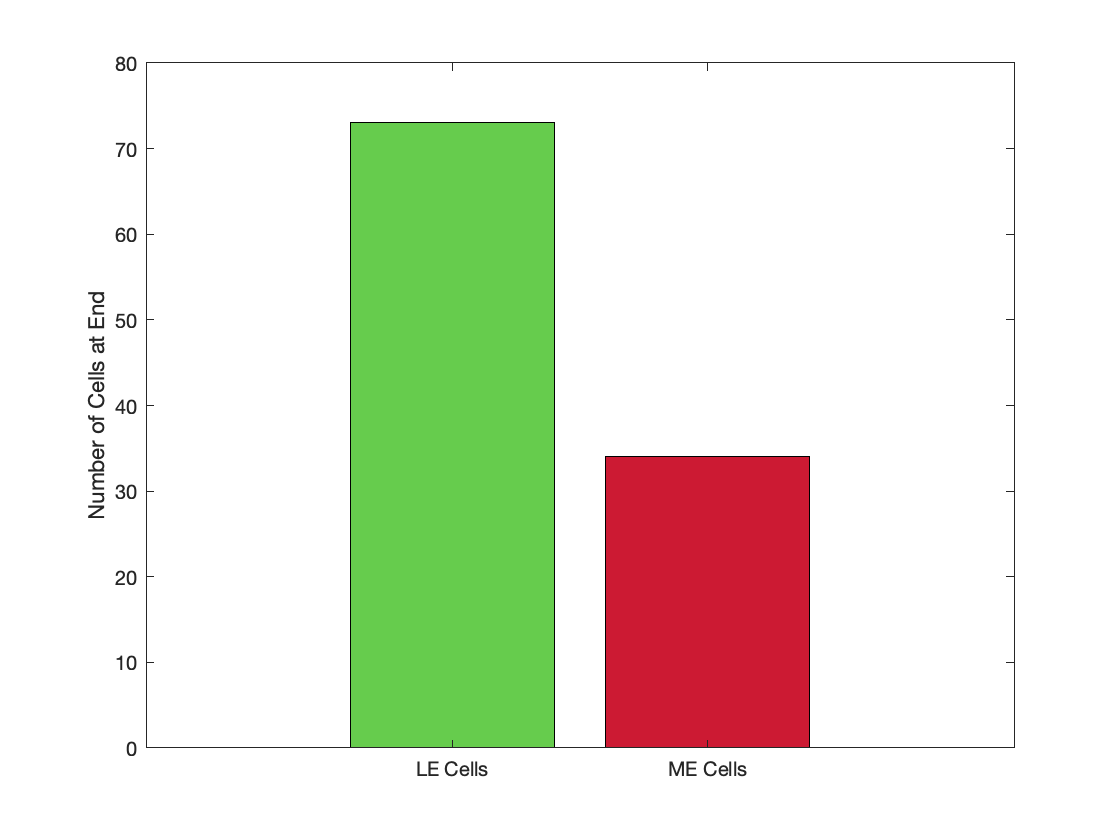

% plot data with error bars
x = [1 2];
WTmeanLE = mean(WTnumberofcells(:,1));
WTmeanME = mean(WTnumberofcells(:,2));
y = [WTmeanLE,WTmeanME];

b = bar(x,y);
ylabel('Number of Cells at End')
ax = gca;
ax.XTick = [1 2]; 
ax.XTickLabels = {'LE Cells', 'ME Cells'};

b.FaceColor = 'flat';
b.CData(1,:) = [.4 .8 .3];
b.CData(2,:) = [.8 .1 .2];

folder = '~/Desktop/';
exportgraphics(gca, 'CellCount_WT.pdf');

movefile('CellCount_WT.pdf', folder);

## ME B1 KO

### n=1

MEB1KO_1 = "/Users/Priya/testoutput/TestMammaryOrganoid/MammaryCellCycleModel/MEB1KO/n=1/results_from_time_0/location.dat";
[MEB1KO_1_numberofcells, x, MEB1KO_1_yLE, MEB1KO_1_yME, MEB1KO_1_yTotal, MEB1KO_1_ME, MEB1KO_1_LE] = TimeVsNoCells(MEB1KO_1);

### n=2

MEB1KO_2 = "/Users/Priya/testoutput/TestMammaryOrganoid/MammaryCellCycleModel/MEB1KO/n=2/results_from_time_0/location.dat";
[MEB1KO_2_numberofcells, x, MEB1KO_2_yLE, MEB1KO_2_yME, MEB1KO_2_yTotal, MEB1KO_2_ME, MEB1KO_2_LE] = TimeVsNoCells(MEB1KO_2);

### n=3

MEB1KO_3 = "/Users/Priya/testoutput/TestMammaryOrganoid/MammaryCellCycleModel/MEB1KO/n=3/results_from_time_0/location.dat";
[MEB1KO_3_numberofcells, x, MEB1KO_3_yLE, MEB1KO_3_yME, MEB1KO_3_yTotal, MEB1KO_3_ME, MEB1KO_3_LE] = TimeVsNoCells(MEB1KO_3);

### n=4

MEB1KO_4 = "/Users/Priya/testoutput/TestMammaryOrganoid/MammaryCellCycleModel/MEB1KO/n=4/results_from_time_0/location.dat";
[MEB1KO_4_numberofcells, x, MEB1KO_4_yLE, MEB1KO_4_yME, MEB1KO_4_yTotal, MEB1KO_4_ME, MEB1KO_4_LE] = TimeVsNoCells(MEB1KO_4);

### n=5

MEB1KO_5 = "/Users/Priya/testoutput/TestMammaryOrganoid/MammaryCellCycleModel/MEB1KO/n=5/results_from_time_0/location.dat";
[MEB1KO_5_numberofcells, x, MEB1KO_5_yLE, MEB1KO_5_yME, MEB1KO_5_yTotal, MEB1KO_5_ME, MEB1KO_5_LE] = TimeVsNoCells(MEB1KO_5);

% combine data tables from all experiments into one table

yTotal_MEB1KO = cat(2,MEB1KO_1_yTotal,MEB1KO_2_yTotal,MEB1KO_3_yTotal,MEB1KO_4_yTotal,MEB1KO_5_yTotal);
yLE_MEB1KO = cat(2,MEB1KO_1_yLE,MEB1KO_2_yLE,MEB1KO_3_yLE,MEB1KO_4_yLE,MEB1KO_5_yLE);
yME_MEB1KO = cat(2,MEB1KO_1_yME,MEB1KO_2_yME,MEB1KO_3_yME,MEB1KO_4_yME,MEB1KO_5_yME);

% transpose data table
time = x.';
yTotal_MEB1KO_ = yTotal_MEB1KO.';
yLE_MEB1KO_ = yLE_MEB1KO.';
yME_MEB1KO_ = yME_MEB1KO.';

% plot data with error bars
clf

hold on; 

MEB1KOtotal = shadedErrorBar(time(:,1:55:end),yTotal_MEB1KO_(:,1:55:end),{@mean,@std},'lineProps','k','transparent',0);

hold off;

hold on;

MEB1KOLE = shadedErrorBar(time(:,1:55:end),yLE_MEB1KO_(:,1:55:end),{@mean,@std},'lineProps','-g','transparent',1);
hold off;

hold on;

MEB1KOME = shadedErrorBar(time(:,1:55:end),yME_MEB1KO_(:,1:55:end),{@mean,@std},'lineProps','-r','transparent',1);

hold off;

ylabel ('Number of Cells')
xlabel('Time (h)')
legend({'Total No. of Cells', 'No. of LE Cells', 'No of ME Cells'}, 'location', 'best')
legend('boxoff')
folder = '~/Desktop/';
exportgraphics(gca, 'FigureCellsvsTime_MEB1KO.pdf');

movefile('FigureCellsvsTime_MEB1KO.pdf', folder);

% combine data from all experiments
MEB1KOnumberofcells = cat(1,MEB1KO_1_numberofcells(end,:),MEB1KO_2_numberofcells(end,:),MEB1KO_3_numberofcells(end,:),MEB1KO_4_numberofcells(end,:),MEB1KO_5_numberofcells(end,:));

% plot data with error bars
x = [1 2];
MEB1KOmeanLE = mean(MEB1KOnumberofcells(:,1));
MEB1KOmeanME = mean(MEB1KOnumberofcells(:,2));
y = [MEB1KOmeanLE,MEB1KOmeanME];

b = bar(x,y);
ylabel('Number of Cells at End')
ax = gca;
ax.XTick = [1 2]; 
ax.XTickLabels = {'LE Cells', 'ME Cells'};

b.FaceColor = 'flat';
b.CData(1,:) = [.4 .8 .3];
b.CData(2,:) = [.8 .1 .2];

folder = '~/Desktop/';
exportgraphics(gca, 'CellCount_MEB1KO.pdf');

movefile('CellCount_MEB1KO.pdf', folder);

## ME KO

### n=1

MEKO_1 = "/Users/Priya/testoutput/TestMammaryOrganoid/MammaryCellCycleModel/MEKO/n=1/results_from_time_0/location.dat";
[MEKO_1_numberofcells, x, MEKO_1_yLE, MEKO_1_yME, MEKO_1_yTotal, MEKO_1_ME, MEKO_1_LE] = TimeVsNoCells(MEKO_1);

### n=2

MEKO_2 = "/Users/Priya/testoutput/TestMammaryOrganoid/MammaryCellCycleModel/MEKO/n=2/results_from_time_0/location.dat";
[MEKO_2_numberofcells, x, MEKO_2_yLE, MEKO_2_yME, MEKO_2_yTotal, MEKO_2_ME, MEKO_2_LE] = TimeVsNoCells(MEKO_2);

### n=3

MEKO_3 = "/Users/Priya/testoutput/TestMammaryOrganoid/MammaryCellCycleModel/MEKO/n=3/results_from_time_0/location.dat";
[MEKO_3_numberofcells, x, MEKO_3_yLE, MEKO_3_yME, MEKO_3_yTotal, MEKO_3_ME, MEKO_3_LE] = TimeVsNoCells(MEKO_3);

### n=4

MEKO_4 = "/Users/Priya/testoutput/TestMammaryOrganoid/MammaryCellCycleModel/MEKO/n=4/results_from_time_0/location.dat";
[MEKO_4_numberofcells, x, MEKO_4_yLE, MEKO_4_yME, MEKO_4_yTotal, MEKO_4_ME, MEKO_4_LE] = TimeVsNoCells(MEKO_4);

### n=5

MEKO_5 = "/Users/Priya/testoutput/TestMammaryOrganoid/MammaryCellCycleModel/MEKO/n=5/results_from_time_0/location.dat";
[MEKO_5_numberofcells, x, MEKO_5_yLE, MEKO_5_yME, MEKO_5_yTotal, MEKO_5_ME, MEKO_5_LE] = TimeVsNoCells(MEKO_5);

% combine data tables from all experiments into one table

yTotal_MEKO = cat(2,MEKO_1_yTotal,MEKO_2_yTotal,MEKO_3_yTotal,MEKO_4_yTotal,MEKO_5_yTotal);
yLE_MEKO = cat(2,MEKO_1_yLE,MEKO_2_yLE,MEKO_3_yLE,MEKO_4_yLE,MEKO_5_yLE);
yME_MEKO = cat(2,MEKO_1_yME,MEKO_2_yME,MEKO_3_yME,MEKO_4_yME,MEKO_5_yME);

% transpose data table
time = x.';
yTotal_MEKO_ = yTotal_MEKO.';
yLE_MEKO_ = yLE_MEKO.';
yME_MEKO_ = yME_MEKO.';

% plot data with error bars
clf

hold on; 

MEKOtotal = shadedErrorBar(time(:,1:55:end),yTotal_MEKO_(:,1:55:end),{@mean,@std},'lineProps','k','transparent',0);

hold off;

hold on;

MEKOLE = shadedErrorBar(time(:,1:55:end),yLE_MEKO_(:,1:55:end),{@mean,@std},'lineProps','-g','transparent',1);
hold off;

hold on;

MEKOME = shadedErrorBar(time(:,1:55:end),yME_MEKO_(:,1:55:end),{@mean,@std},'lineProps','-r','transparent',1);

hold off;

ylabel ('Number of Cells')
xlabel('Time (h)')
legend({'Total No. of Cells', 'No. of LE Cells', 'No of ME Cells'}, 'location', 'best')
legend('boxoff')
folder = '~/Desktop/';
exportgraphics(gca, 'FigureCellsvsTime_MEKO.pdf');

movefile('FigureCellsvsTime_MEKO.pdf', folder);

% combine data from all experiments
MEKOnumberofcells = cat(1,MEKO_1_numberofcells(end,:),MEKO_2_numberofcells(end,:),MEKO_3_numberofcells(end,:),MEKO_4_numberofcells(end,:),MEKO_5_numberofcells(end,:));

% plot data with error bars
x = [1 2];
MEKOmeanLE = mean(MEKOnumberofcells(:,1));
MEKOmeanME = mean(MEKOnumberofcells(:,2));
y = [MEKOmeanLE,MEKOmeanME];

b = bar(x,y);
ylabel('Number of Cells at End')
ax = gca;
ax.XTick = [1 2]; 
ax.XTickLabels = {'LE Cells', 'ME Cells'};

b.FaceColor = 'flat';
b.CData(1,:) = [.4 .8 .3];
b.CData(2,:) = [.8 .1 .2];

folder = '~/Desktop/';
exportgraphics(gca, 'CellCount_MEKO.pdf');

movefile('CellCount_MEKO.pdf', folder);

## DO KO

### n=1

DOKO_1 = "/Users/Priya/testoutput/TestMammaryOrganoid/MammaryCellCycleModel/DOKO/n=1/results_from_time_0/location.dat";
[DOKO_1_numberofcells, x, DOKO_1_yLE, DOKO_1_yME, DOKO_1_yTotal, DOKO_1_ME, DOKO_1_LE] = TimeVsNoCells(DOKO_1);

### n=2

DOKO_2 = "/Users/Priya/testoutput/TestMammaryOrganoid/MammaryCellCycleModel/DOKO/n=2/results_from_time_0/location.dat";
[DOKO_2_numberofcells, x, DOKO_2_yLE, DOKO_2_yME, DOKO_2_yTotal, DOKO_2_ME, DOKO_2_LE] = TimeVsNoCells(DOKO_2);

### n=3

DOKO_3 = "/Users/Priya/testoutput/TestMammaryOrganoid/MammaryCellCycleModel/DOKO/n=3/results_from_time_0/location.dat";
[DOKO_3_numberofcells, x, DOKO_3_yLE, DOKO_3_yME, DOKO_3_yTotal, DOKO_3_ME, DOKO_3_LE] = TimeVsNoCells(DOKO_3);

### n=4

DOKO_4 = "/Users/Priya/testoutput/TestMammaryOrganoid/MammaryCellCycleModel/DOKO/n=4/results_from_time_0/location.dat";
[DOKO_4_numberofcells, x, DOKO_4_yLE, DOKO_4_yME, DOKO_4_yTotal, DOKO_4_ME, DOKO_4_LE] = TimeVsNoCells(DOKO_4);

### n=5

DOKO_5 = "/Users/Priya/testoutput/TestMammaryOrganoid/MammaryCellCycleModel/DOKO/n=5/results_from_time_0/location.dat";
[DOKO_5_numberofcells, x, DOKO_5_yLE, DOKO_5_yME, DOKO_5_yTotal, DOKO_5_ME, DOKO_5_LE] = TimeVsNoCells(DOKO_5);

% combine data tables from all experiments into one table

yTotal_DOKO = cat(2,DOKO_1_yTotal,DOKO_2_yTotal,DOKO_3_yTotal,DOKO_4_yTotal,DOKO_5_yTotal);
yLE_DOKO = cat(2,DOKO_1_yLE,DOKO_2_yLE,DOKO_3_yLE,DOKO_4_yLE,DOKO_5_yLE);
yME_DOKO = cat(2,DOKO_1_yME,DOKO_2_yME,DOKO_3_yME,DOKO_4_yME,DOKO_5_yME);

% transpose data table
time = x.';
yTotal_DOKO_ = yTotal_DOKO.';
yLE_DOKO_ = yLE_DOKO.';
yME_DOKO_ = yME_DOKO.';

% plot data with error bars
clf

hold on; 

DOKOtotal = shadedErrorBar(time(:,1:55:end),yTotal_DOKO_(:,1:55:end),{@mean,@std},'lineProps','k','transparent',0);

hold off;

hold on;

DOKOLE = shadedErrorBar(time(:,1:55:end),yLE_DOKO_(:,1:55:end),{@mean,@std},'lineProps','-g','transparent',1);
hold off;

hold on;

DOKOME = shadedErrorBar(time(:,1:55:end),yME_DOKO_(:,1:55:end),{@mean,@std},'lineProps','-r','transparent',1);

hold off;

ylabel ('Number of Cells')
xlabel('Time (h)')
legend({'Total No. of Cells', 'No. of LE Cells', 'No of ME Cells'}, 'location', 'best')
legend('boxoff')
folder = '~/Desktop/';
exportgraphics(gca, 'FigureCellsvsTime_DOKO.pdf');

movefile('FigureCellsvsTime_DOKO.pdf', folder);

% combine data from all experiments
DOKOnumberofcells = cat(1,DOKO_1_numberofcells(end,:),DOKO_2_numberofcells(end,:),DOKO_3_numberofcells(end,:),DOKO_4_numberofcells(end,:),DOKO_5_numberofcells(end,:));

% plot data with error bars
x = [1 2];
DOKOmeanLE = mean(DOKOnumberofcells(:,1));
DOKOmeanME = mean(DOKOnumberofcells(:,2));
y = [DOKOmeanLE,DOKOmeanME];

b = bar(x,y);
ylabel('Number of Cells at End')
ax = gca;
ax.XTick = [1 2]; 
ax.XTickLabels = {'LE Cells', 'ME Cells'};

b.FaceColor = 'flat';
b.CData(1,:) = [.4 .8 .3];
b.CData(2,:) = [.8 .1 .2];

folder = '~/Desktop/';
exportgraphics(gca, 'CellCount_DOKO.pdf');

movefile('CellCount_DOKO.pdf', folder);